Referências E exercícios

6.7. SUGESTÕES DE EXERCÍCIOS (KLAUS - AMSD)

Kuo 9a ed: 9-9 a 9-11, 9-13, 9-14, 9-34, 9-37, 9-38, 9-40, 9-41, 9-44, 9-47, 9-51, 9-53 “a” e “b”.

Seborg 2a ed: 12.1 a 12.3, 12.5a, 12.7 a 12.11, 12.13, 12.14

PID

Equação geral do PID

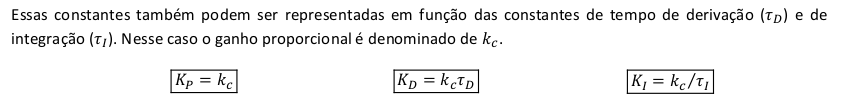

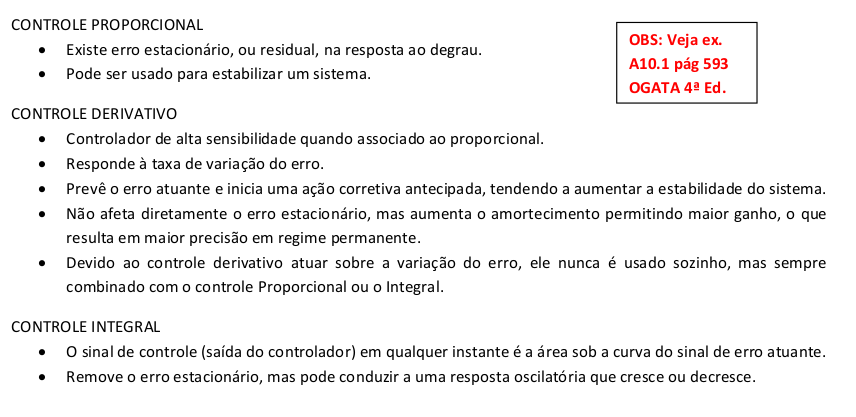

Foda é entender matematicamente o motivo disso acontecer.

IAE

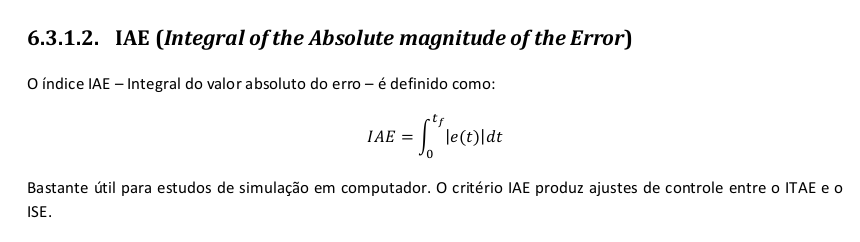

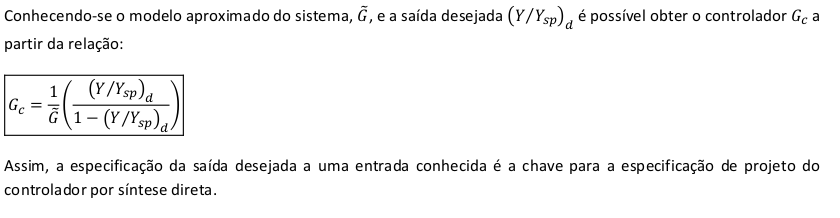

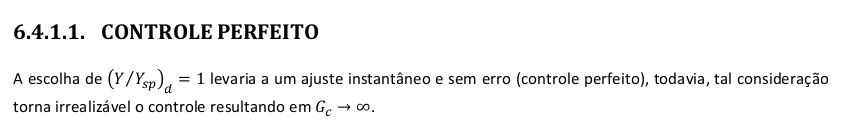

**Tá, mas que porra é essa de integrativo e derivativo?**

Simples, o integrativo e derivativo vêm da transformada de laplace

 Integrativo (veja a posição do s)

Toda vez que vc ver um inferno de s no denominador, então ele tem um efeito integrativo.

 Derivativo f(0) = 0 (sistema inicia sem condições iniciais) e veja a posição do s.

Vamos escolher o tipo de resposta que queremos. Se a gente quer a planta responda como um sistema de primeira ordem sem atraso de tempo, então vamos escolher

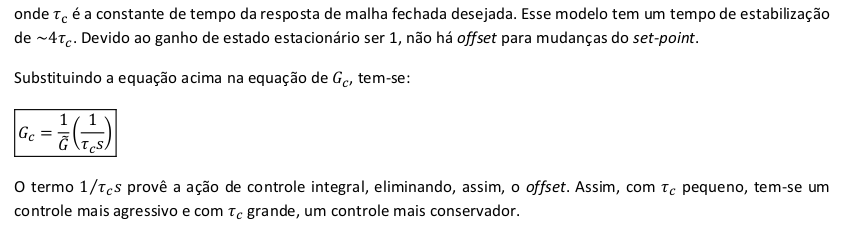

Com atraso

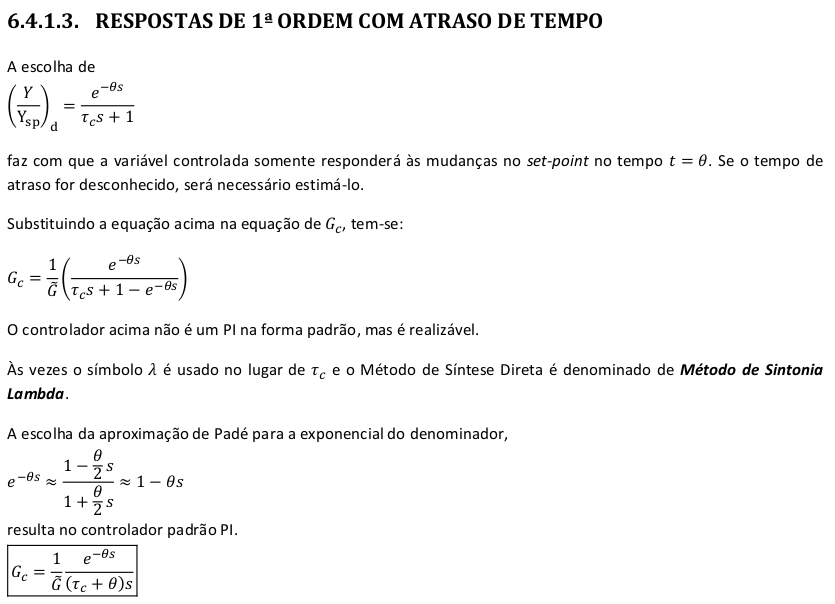

Ou seja, padé adiciona um zero no tempo morto.

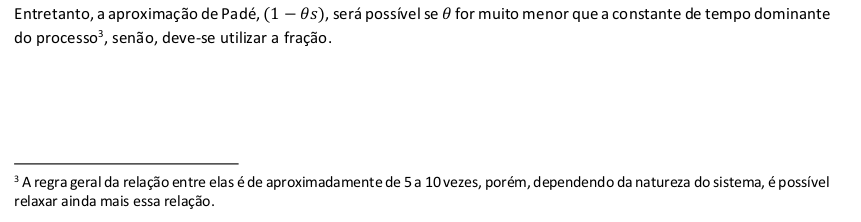

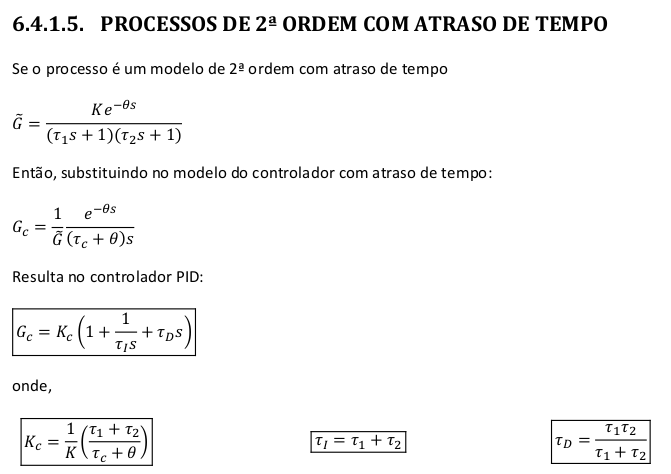

esse aqui então virou só gravar fórmula.

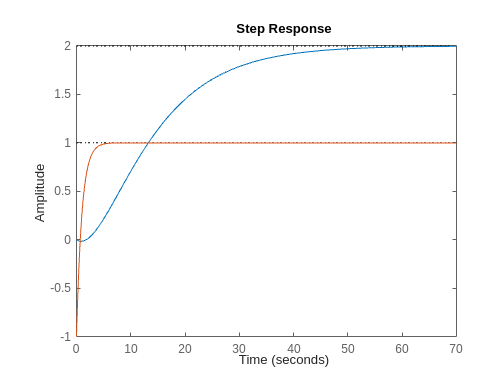

s = tf('s');
G = 2*(1-s)/((10*s + 1)*(5*s + 1));
PI = 1/(15*s);
PD = 10*s/3;
Gc = (15/4)*(1 + PI + PD);
M = feedback(Gc*G,1);
step(G,M)

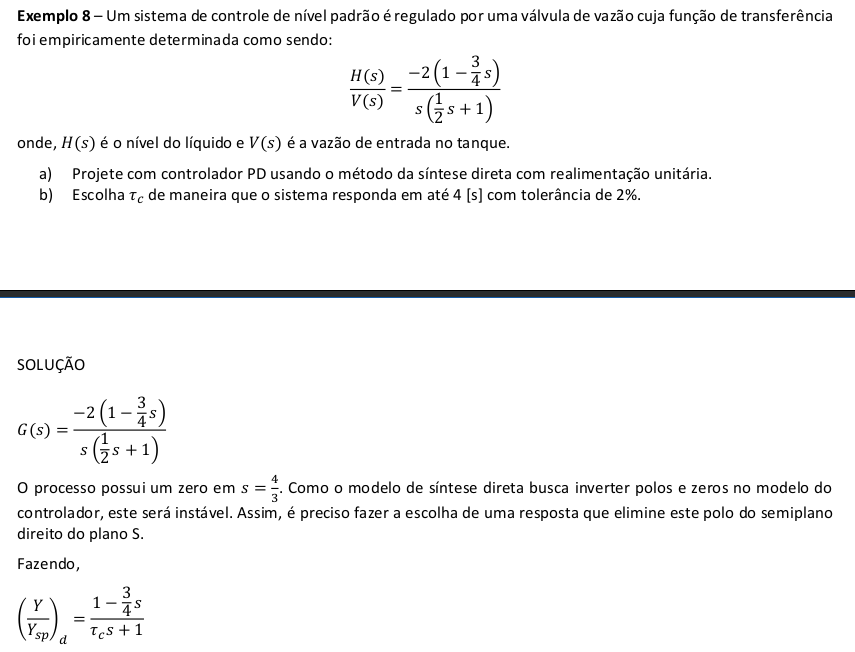

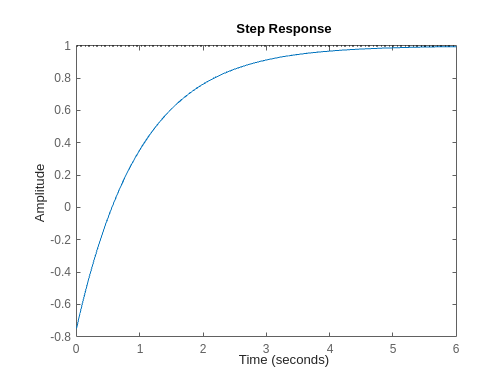

num = -2*(1-3*s/4);
den = s*(0.5*s + 1);
G = num/den;
PD = 0.5*s;
Gc = -2*(1+PD)/7;
M = feedback(G*Gc,1);
step(M)

né que o negócio funciona mesmo?

zigbee

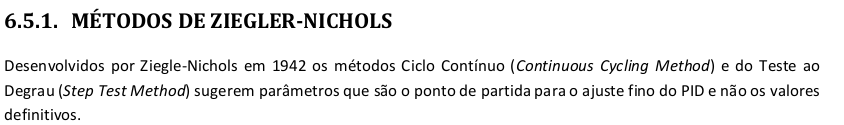

DORF

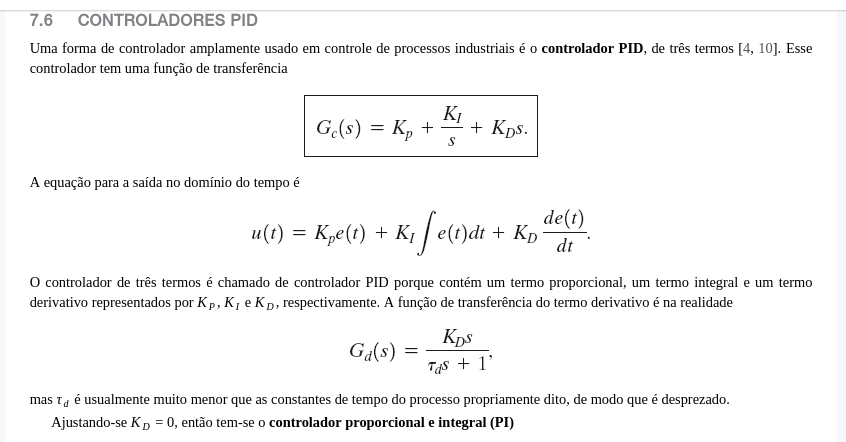

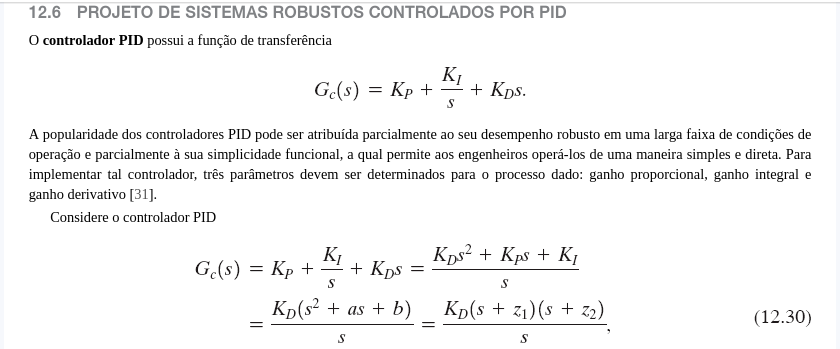

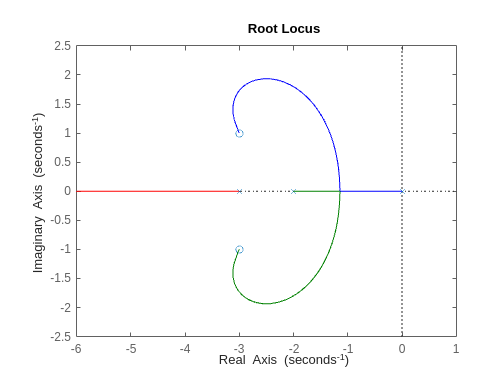

G = 1/((s+2)*(s+3));
GC = (s^2 + 6*s + 10)/s;
M = feedback(G,1);
MC = feedback(GC*G,1);
rlocus(GC*G)

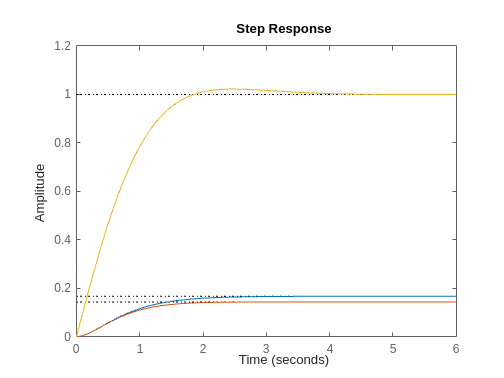

step(G,M,MCS)